clc;clearvars;
global env Tx_xyz RIS_xyz Rx_xyz N Frequency siso
tic
siso = 1; % 1 ise siso var, 0 ise yok
env = 1;
Frequency=28;
pdfpoints = 0;
TOTAL = 2000;

## zris = 1, n = 256

Tx_xyz=[0,25,2];
Rx_xyz=[38,48,1];
RIS_xyz=[40,50,1];

N = 256;

vals = zeros(1,TOTAL);
for ii = 1:TOTAL
    fprintf("zris1 256 ii ="+ii+"\n");
    vals(ii) = SimRISv1();
end

zris1 256 ii =1
zris1 256 ii =2
zris1 256 ii =3
zris1 256 ii =4
zris1 256 ii =5
zris1 256 ii =6
zris1 256 ii =7
zris1 256 ii =8
zris1 256 ii =9
zris1 256 ii =10
zris1 256 ii =11
zris1 256 ii =12
zris1 256 ii =13
zris1 256 ii =14
zris1 256 ii =15
zris1 256 ii =16
zris1 256 ii =17
zris1 256 ii =18
zris1 256 ii =19
zris1 256 ii =20
zris1 256 ii =21
zris1 256 ii =22
zris1 256 ii =23
zris1 256 ii =24
zris1 256 ii =25
zris1 256 ii =26
zris1 256 ii =27
zris1 256 ii =28
zris1 256 ii =29
zris1 256 ii =30
zris1 256 ii =31
zris1 256 ii =32
zris1 256 ii =33
zris1 256 ii =34
zris1 256 ii =35
zris1 256 ii =36
zris1 256 ii =37
zris1 256 ii =38
zris1 256 ii =39
zris1 256 ii =40
zris1 256 ii =41
zris1 256 ii =42
zris1 256 ii =43
zris1 256 ii =44
zris1 256 ii =45
zris1 256 ii =46
zris1 256 ii =47
zris1 256 ii =48
zris1 256 ii =49
zris1 256 ii =50
zris1 256 ii =51
zris1 256 ii =52
zris1 256 ii =53
zris1 256 ii =54
zris1 256 ii =55
zris1 256 ii =56
zris1 256 ii =57
zris1 256 ii =58
zris1 256 ii =59
zris1 

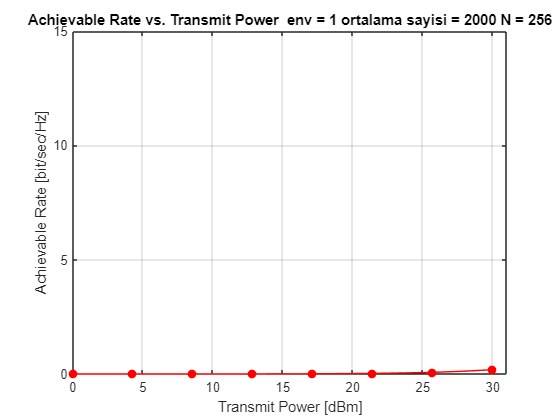

saved = mean(vals);


Pt = logspace(-3,0,50); % 1e-3 to 1
No = db2pow(-130);      % -100 dBm

SNR = (((abs(saved)^2)/No)).*Pt;
R = log2(1+SNR);

save("v1_siso_N256zris1.mat");

plot(pow2db(Pt)+30,R,'r-o','MarkerFaceColor','r','MarkerIndices',1:7:50);
title('Achievable Rate vs. Transmit Power ' +" env = " + env + " ortalama sayisi = " + TOTAL + " N = " + N)
ylabel('Achievable Rate [bit/sec/Hz]')
xlabel('Transmit Power [dBm]')
ylim([0 15])
xlim([0 31])
grid on;
hold on;

## zris = 2, n = 256

Tx_xyz=[0,25,2];
Rx_xyz=[38,48,1];
RIS_xyz=[40,50,2];

N = 256;

vals = zeros(1,TOTAL);
for ii = 1:TOTAL
    fprintf("zris2 256 ii ="+ii+"\n");
    vals(ii) = SimRISv1();
end

zris2 256 ii =1
zris2 256 ii =2
zris2 256 ii =3
zris2 256 ii =4
zris2 256 ii =5
zris2 256 ii =6
zris2 256 ii =7
zris2 256 ii =8
zris2 256 ii =9
zris2 256 ii =10
zris2 256 ii =11
zris2 256 ii =12
zris2 256 ii =13
zris2 256 ii =14
zris2 256 ii =15
zris2 256 ii =16
zris2 256 ii =17
zris2 256 ii =18
zris2 256 ii =19
zris2 256 ii =20
zris2 256 ii =21
zris2 256 ii =22
zris2 256 ii =23
zris2 256 ii =24
zris2 256 ii =25
zris2 256 ii =26
zris2 256 ii =27
zris2 256 ii =28
zris2 256 ii =29
zris2 256 ii =30
zris2 256 ii =31
zris2 256 ii =32
zris2 256 ii =33
zris2 256 ii =34
zris2 256 ii =35
zris2 256 ii =36
zris2 256 ii =37
zris2 256 ii =38
zris2 256 ii =39
zris2 256 ii =40
zris2 256 ii =41
zris2 256 ii =42
zris2 256 ii =43
zris2 256 ii =44
zris2 256 ii =45
zris2 256 ii =46
zris2 256 ii =47
zris2 256 ii =48
zris2 256 ii =49
zris2 256 ii =50
zris2 256 ii =51
zris2 256 ii =52
zris2 256 ii =53
zris2 256 ii =54
zris2 256 ii =55
zris2 256 ii =56
zris2 256 ii =57
zris2 256 ii =58
zris2 256 ii =59
zris2 

saved = mean(vals);


Pt = logspace(-3,0,50);
No = db2pow(-130);

SNR = (((abs(saved)^2)/No)).*Pt;
R = log2(1+SNR);

save("v1_siso_N256zris2.mat");

plot(pow2db(Pt)+30,R,'r-^','MarkerFaceColor','r','MarkerIndices',1:7:50);
title('Achievable Rate vs. Transmit Power ' +" env = " + env + " ortalama sayisi = " + TOTAL + " N = " + N)
ylabel('Achievable Rate [bit/sec/Hz]')
xlabel('Transmit Power [dBm]')
ylim([0 15])
xlim([0 31])
grid on;
hold on;

## zris = 1, n = 1024

Tx_xyz=[0,25,2];
Rx_xyz=[38,48,1];
RIS_xyz=[40,50,1];

N = 1024;

vals = zeros(1,TOTAL);
for ii = 1:TOTAL
    fprintf("zris1 1024 ii ="+ii+"\n");
    vals(ii) = SimRISv1();
end
saved = mean(vals);


Pt = logspace(-3,0,50);
No = db2pow(-130);

SNR = (((abs(saved)^2)/No)).*Pt;
R = log2(1+SNR);

save("v1_siso_N1024zris1.mat");

plot(pow2db(Pt)+30,R,'b-o','MarkerFaceColor','b','MarkerIndices',1:7:50);
title('Achievable Rate vs. Transmit Power ' +" env = " + env + " ortalama sayisi = " + TOTAL + " N = " + N)
ylabel('Achievable Rate [bit/sec/Hz]')
xlabel('Transmit Power [dBm]')
ylim([0 15])
xlim([0 31])
grid on;
hold on;

## zris = 2, n = 1024

Tx_xyz=[0,25,2];
Rx_xyz=[38,48,1];
RIS_xyz=[40,50,2];

N = 1024;

vals = zeros(1,TOTAL);
for ii = 1:TOTAL
    fprintf("zris2 1024 ii ="+ii+"\n");
    vals(ii) = SimRISv1();
end
saved = mean(vals);


Pt = logspace(-3,0,50);
No = db2pow(-130);

SNR = (((abs(saved)^2)/No)).*Pt;
R = log2(1+SNR);

save("v1_siso_N1024zris2.mat");

plot(pow2db(Pt)+30,R,'b-^','MarkerFaceColor','b','MarkerIndices',1:7:50);
title('Achievable Rate vs. Transmit Power ' +" env = " + env + " ortalama sayisi = " + TOTAL + " N = " + N)
ylabel('Achievable Rate [bit/sec/Hz]')
xlabel('Transmit Power [dBm]')
ylim([0 15])
xlim([0 31])
grid on;
hold on;